clc, clearvars

%declarando variáveis
char inputFile outPutFile;
double startTime;
double endTime;

%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Somente preencher o q estah escrito aki
% adicionando o arquivo
inputFile = 'senf020a200Ent';
outputFile = 'senf020a200Sai';

%escolhendo a parte de interesse
startTime = 7;
endTime = 14;
np = 4;
%%%%%%%%%%%%%%%%%%%%%%%%%%%

%ajustando os dados para matrizes de tempo e amplitude
input = importdata(inputFile + ".mat");
inputTime = input.([inputFile '_Time']);
inputAmplitude = input.([inputFile '_Value']);

output = importdata(outputFile + ".mat");
outputTime = output.([outputFile '_Time']);
outputAmplitude = output.([outputFile '_Value']);


startIndex = find(inputTime >= startTime, 1);
endIndex = find(inputTime >= endTime, 1);

inputTimeRange = inputTime(startIndex:endIndex);
inputAmplitudeRange = inputAmplitude(startIndex:endIndex);

outputTimeRange = outputTime(startIndex:endIndex,:);
outputAmplitudeRange = outputAmplitude(startIndex:endIndex,:);

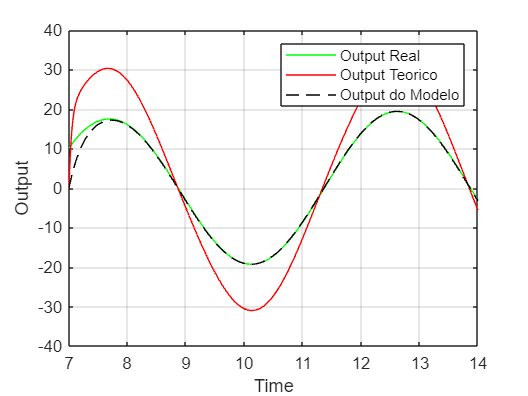

time = seconds(startTime:0.01:endTime);

dataTeor = double([inputAmplitudeRange, outputAmplitudeRange(:,1)]);
dataReal = double([inputAmplitudeRange, outputAmplitudeRange(:,2)]);

ttTeor = array2timetable(dataTeor, "RowTimes",time);
ttReal = array2timetable(dataReal, "RowTimes",time);

tfTeor = tfest(ttTeor, np);
tfReal = tfest(ttReal, np);

% tfTeor.Numerator;
% tfTeor.Denominator;
%
num = tfReal.Numerator;
den = tfReal.Denominator;

model_output_teor = lsim(tfTeor, inputAmplitudeRange, inputTimeRange);
model_output_real = lsim(tfReal, inputAmplitudeRange, inputTimeRange);

figure;
plot(inputTimeRange, outputAmplitudeRange(:,2), 'g', inputTimeRange, model_output_teor, 'r-');
hold on
plot(inputTimeRange, model_output_real, 'black--');
legend('Output Real','Output Teorico' ,'Output do Modelo');
xlabel('Time');
ylabel('Output');
grid on
hold off

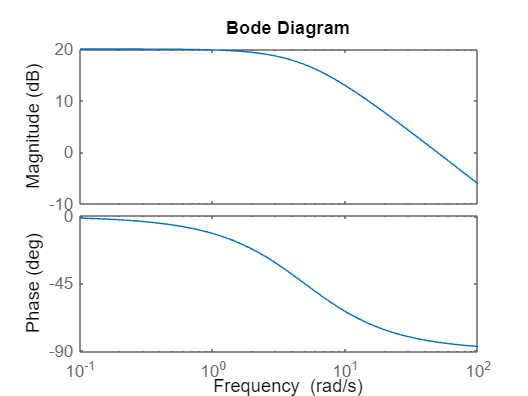

figure;
H = tf(num,den);
bode(H);